# Neural networks

This live script implements a feed forward neural network from scratch. The network is used for binary classification. Any number of layers can be used, and any number of hidden units can be used per layer. The tanh activation function is used. The residual sum of squares error function is minimized using gradient descent to find the neural network weights.

We'll test the network on a very simple problem. You can take this script further by testing the network on more complex data. Here, we generate 2-dimensional data that can be separated by a linear discriminant.

rng(0);
n = 15;
x = rand(2,n);

% generate +1/-1 labels separated by a discriminant function
w = [.3 .5 -1]';
y = zeros(1,n);
for i = 1:n
  y(i) = sign(w'*[1; x(1,i); x(2,i)]);
end

We specify the neural network architecture by defining the weight matrices that initially contain random weights. We'll use 2 layers, but you can use any number of layers you like.

% h(x) = actfun(b2 + W2' * actfun(b1 + W1' x));
L = 2; % number of layers
W = cell(L,1);
W{1} = rand(2,2)-.5;
W{2} = rand(2,1)-.5;
b = cell(L,1);
b{1} = rand(2,1)-.5;
b{2} = rand(1,1)-.5;

Now train the network by calling our own gradient descent function (implemented below).

[W, b] = gradient_descent(x, y, W, b);

     0   18.575115
   100   0.009228
   200   0.004205
   300   0.002712
   400   0.001995
   500   0.001574
   600   0.001298
   700   0.001103
   800   0.000958
   900   0.000846
  1000   0.000758
  1100   0.000685
  1200   0.000625
  1300   0.000575
  1400   0.000532
  1500   0.000495
  1600   0.000462
  1700   0.000434
  1800   0.000409
  1900   0.000386
  2000   0.000366
  2100   0.000348
  2200   0.000331
  2300   0.000316
  2400   0.000302
  2500   0.000290
  2600   0.000278
  2700   0.000267
  2800   0.000257
  2900   0.000248
  3000   0.000239
  3100   0.000231
  3200   0.000224
  3300   0.000216
  3400   0.000210
  3500   0.000204
  3600   0.000198
  3700   0.000192
  3800   0.000187
  3900   0.000182
  4000   0.000177
  4100   0.000172
  4200   0.000168
  4300   0.000164
  4400   0.000160
  4500   0.000156
  4600   0.000153
  4700   0.000150
  4800   0.000146
  4900   0.000143
  5000   0.000140
  5100   0.000137
  5200   0.000135
  5300   0.000132
  5400   0.000129
  5500   

Plot the training points.

for i = 1:size(x,2)
  if y(i) > 0
    plot(x(1,i), x(2,i), 'bo'); hold on
  else
    plot(x(1,i), x(2,i), 'kx'); hold on
  end
end

Predict and plot labels for random test points.

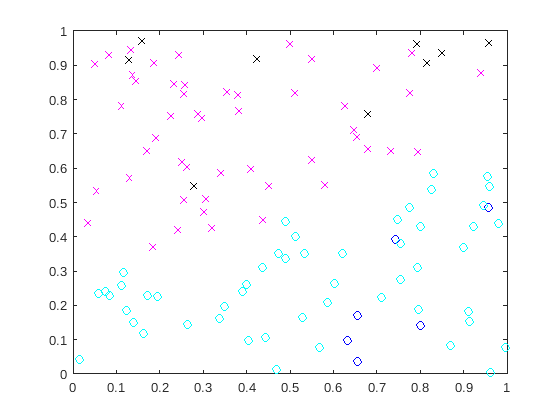

for i = 1:100
  x = rand(2,1);
  h = neuralnet_predict(x, W, b);
  if h > 0
    plot(x(1), x(2), 'co'); hold on
  else
    plot(x(1), x(2), 'mx'); hold on
  end
end

For this training data, the neural network seems to classify points using a linear discriminant. You can check if this is really true by classifying a very large number of points. How does this discriminant compare to the ground truth discriminant used to generate the data?

Here is the code for gradient descent.

function [W, b] = gradient_descent(x, y, W, b)

% print initial objective value
v = neuralnet_lossfun(x, y, W, b);
fprintf('%6d   %f\n', 0, v);

eta = 0.1;
for i = 1:10000
  [dW, db] = neuralnet_gradient(x, y, W, b);
  for l = 1:length(W)
    % W = W - eta*dW;
    % b = b - eta*db;
    W{l} = W{l} - eta*dW{l};
    b{l} = b{l} - eta*db{l};
  end
  v = neuralnet_lossfun(x, y, W, b);
  if mod(i,100) == 0
    fprintf('%6d   %f\n', i, v);
  end
end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function v = neuralnet_lossfun(x, y, W, b)
v = 0;
for p = 1:size(x,2)
  h = neuralnet_predict(x(:,p), W, b);
  v = v + (h - y(p))^2;
end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function x = neuralnet_predict(x, W, b)
for l = 1:length(W)
  x = actfun(b{l} + W{l}'*x);
end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [dW, db] = neuralnet_gradient(x, y, W, b)

% number of layers
L = length(W);

% parts of the gradient
dW = cell(L,1);
db = cell(L,1);
for l = 1:L
  dW{l} = zeros(size(W{l}));
  db{l} = zeros(size(b{l}));
end

s = cell(L,1); % activations
z = cell(L,1); % post-activations
d = cell(L,1); % sensitivities

% loop over data points
% an optimization is to make this the inner loop
n = size(x,2);
for p = 1:n

  % forward propagation
  temp = x(:,p);
  for l = 1:L
    s{l} = b{l} + W{l}'*temp;
    z{l} = actfun(s{l});
    temp = z{l};
  end

  % back propagation to compute sensitivities;
  % note biases are not used
  d{L} = dactfun(s{L});
  for l = L-1:-1:1
    d{l} = (W{l+1}*d{l+1}) .* dactfun(s{l});
  end

  % compute gradient (accumulate for each data point)
  errorfun_factor = 2*(z{L} - y(p)); % could premultiply into each d{l} if many layers
  temp = x(:,p);
  for l = 1:L
    dW{l} = dW{l} + temp*d{l}'*errorfun_factor;  % outer product
    db{l} = db{l} + d{l}*errorfun_factor;
    temp = z{l};
  end

end
end

function z = actfun(s)
% activation function
z = tanh(s);
end

function z = dactfun(s)
% derivative of activation function
z = tanh(s); % an optimization is to not compute tanh again (computed already in actfun)
z = 1 - z.*z;
end

### Taking it further

How does the code work for more complicated data, in particular data that cannot be separated by a linear discriminant?

For your more complicated data, also experiment with different numbers of layers and different numbers of units in each layer. Can your network work for your more complicated data?

Modify the neural network to use the logistic sigmoid activation function in the output layer and also the cross-entropy loss function for the minimization objective.

See if you an observe a regularization effect by changing the number of hidden units in each layer.

Modify the neural network to use weight decay for regularization.